Tämä skripti sisältää kandidaatintyöhön sisältyvän testauksen. Siinä on useita osioita, ja ne ovat siinä järjestyksessä, miten testit ovat edenneet.

Init

 
% Poista kaikki entiset muuttujat, ikkunat ja komentohistoria
clc
clear all
close all

% Lisää alihakemistot
mainfolder = getPath;
addpath(genpath(strcat(mainfolder,'\Algorithms')));
addpath(genpath(strcat(mainfolder,'\Tools')));

Tallenna data

 
choose = "saved"

choose = "saved"


if choose == "sensor"
    % tallenna anturista
    time = 60;
    topic = "velodyne_points";
    IP_address = "127.0.0.1";
    pcSet = saveRosData(time, topic, IP_address);

elseif choose == "saved"
    % Vaihtoehtoisesti käytetään tallennettua dataa.
    % Tallenna datapaketti osoitteesta:
    % https://tuni-my.sharepoint.com/:f:/g/personal/markus_hautala_tuni_fi/EqMrzbfX0W1BkObC2WGypbwBZJshim-_KwTy8prTLD4_nw?e=M3OFuB
    load("savedData.mat")

end

Esikäsittelytestaus yksittäiselle pistepilvelle

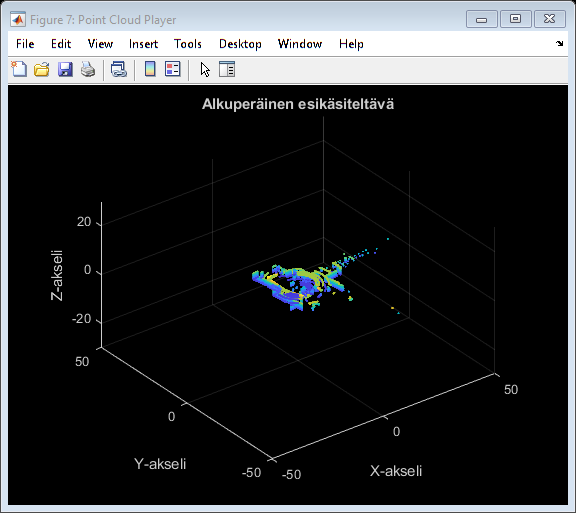

 
show1 = showPc('Alkuperäinen esikäsiteltävä', pc);

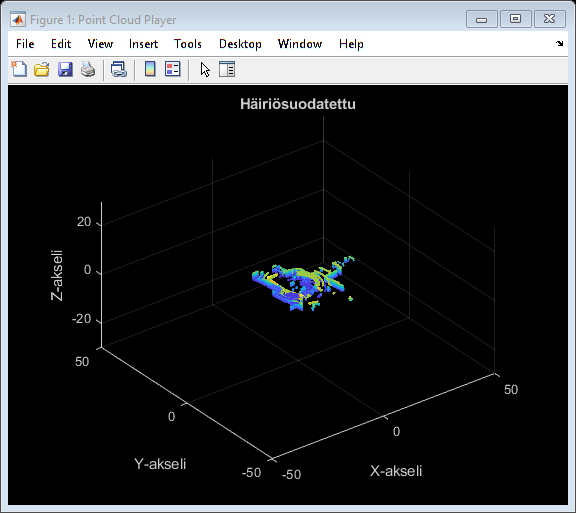


%% Häiriösuodatus
pc_denoised = pcdenoise(pc);
show2 = showPc('Häiriösuodatettu', pc_denoised);


% Kuinka paljon pisteitä hävisi:
losed_points = size_of_pc(pc) - size_of_pc(pc_denoised)

losed_points = 35



%% Alinäytteistys
laatikon_koko = 0.1; % (m)
tic
pc_downsampled_grid = pcdownsample(pc, 'gridAverage', laatikon_koko);
time_of_grid = toc

time_of_grid = 0.0252

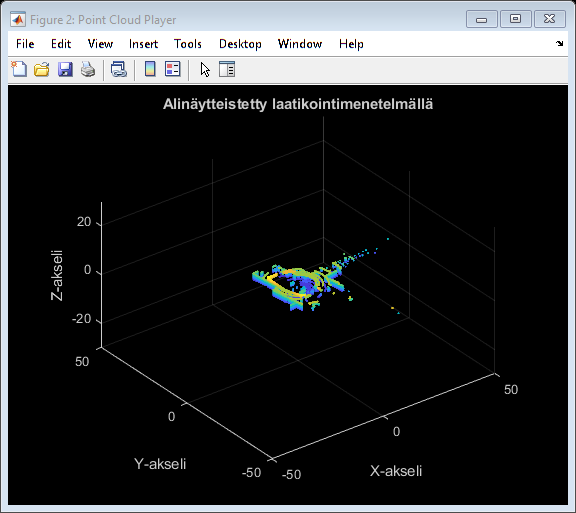

show3 = showPc('Alinäytteistetty laatikointimenetelmällä', pc_downsampled_grid);


% Prosentuaalinen pistepilven koko verrattuna ennen alinäytteistystä:
pros_koko = size_of_pc(pc_downsampled_grid) / size_of_pc(pc)

pros_koko = 0.3844


% Verrataan satunnaismenetelmään:
tic
pc_downsampled_rand = pcdownsample(pc, "random", pros_koko);
time_of_random = toc

time_of_random = 0.0120

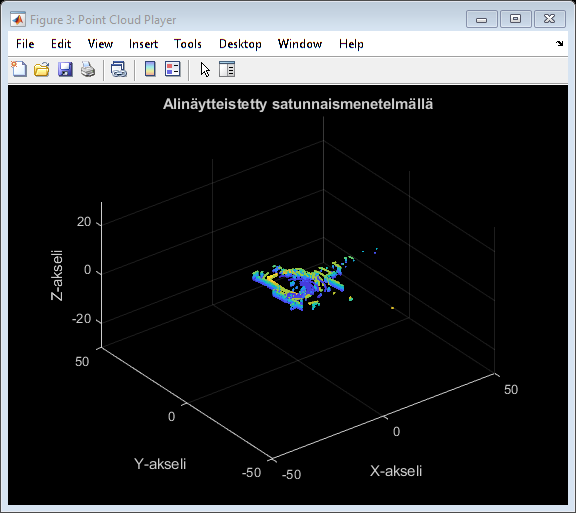

show4 = showPc('Alinäytteistetty satunnaismenetelmällä', pc_downsampled_rand);

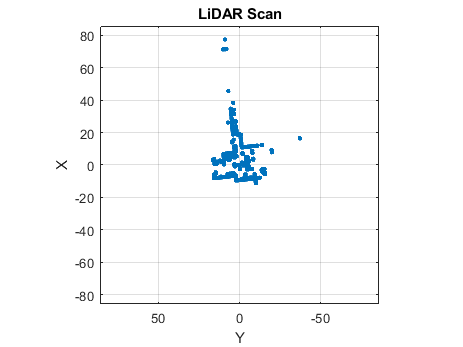



% 3D to 2D
lidarScan_limited = pc2laser({pc}, -0.5, 1.5);
figure
plot(lidarScan_limited{1});

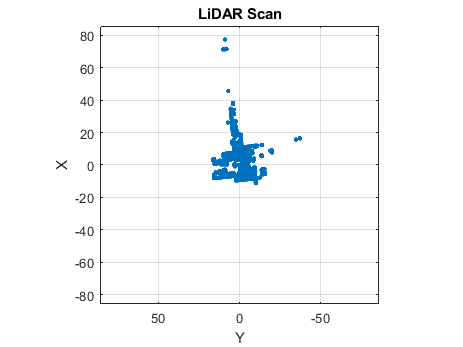


lidarScan_unlimited = pc2laser({pc}, -50, 50);
figure
plot(lidarScan_unlimited{1});

Esikäsittely SLAM algoritmeille

 
eachFrame = 10;
preprocessedpcSet = preprocess(pcSet, eachFrame);
lidarSet = pc2laser(preprocessedpcSet, -0.5, 1.5);
size_of_psSet(preprocessedpcSet)